# Signals and Systems - LAB 1

## Matrices Manipulations

a=2;
b=[1 3 2];
c=[2 5 1];

Various operations can be performed.

a+b

ans =      3     5     4


b*c

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Related documentation

Why did the previous command give an error? How can it be corrected?

b^2

A = round(4*randn(3,3))
det(A)
inv(A)
inv(A)*A
size(A)
length(A)

A(:)
A(:,3)

## Complex Numbers

clear all;
A = 3 + j*2 ; B = -1+j*6 ;
A + B
A - B
A*B
A/B
abs(A)
angle(A)


## Two Dimensional Plots

t = 0:1/32:2 ;
x = sin(2*pi*t) ;
plot(t,x) ;

plot(t,x,'ro') ;

y = cos(2*pi*t) ;
plot(t,x,'k--',t,y,'r:') ;

title('Plot demonstrating annotation commands') ;
xlabel('x Label') ;
ylabel('y Label') ;

text(1,0,'Text label') ;

Another Example

years = (1900:10:2000);                                  % Time interval
pop = [75.995 91.972 105.711 123.203 131.669 ...         % Population Data
    150.697 179.323 213.212 228.505 250.633 265.422]
plot(years,pop,'bo');                                    % Plot the population data
axis([1900 2020 0 500]);
title('Population of the U.S. 1900-2000');
ylabel('Millions');
xlabel('Year')
ylim([50 300])

## Three Dimensional Plots

clear all;
t = 0:1/32:2 ;
plot3(t,cos(2*pi*t),sin(2*pi*t)) ;
grid on ;
xlabel('t') ; ylabel('cos(2*pi*t)') ; zlabel('sin(2*pi*t)') ;

## Creating Functions

clear all;
f=5;
w=2*pi*f;
t=-1:0.001:1;
s=sin(w*t);
plot(t,s);
title('plot of sine wave-approximation to analog sine wave is plotted');
xlabel('time');
ylabel('amplitude');

Another example

clear all
f=10;
T=0.01;
for n=1:21;
   x(n)=sin(2*pi*f*(n-1)*T);
end
stem(x);
title('plot of DT signal x');
xlabel('sample number');
ylabel('amplitude');

Shifting a sinusoidal

clear all;
f=5;
theta=45;
w=2*pi*f;
t=0:0.001:1;
s=sin(w*t+((theta*pi)/180));
plot(t,s);
title('plot of sine wave with phase shift theta of 45 degrees')
xlabel('time');
ylabel('amplitude');

Plotting a ramp

clear all;
t=0:0.1:1;
x=0.01*t;
plot(t,x);
title('plot of signal x');
xlabel('time');ylabel('amplitude');

Plotting a square

clear all;
t=0:1:2;

for i=1:2
    x(i)=-1;
    x(i)=1;
end
t=2:1:4;

for i=2:4
    x(i)=1;
end
plot(x)
title('plot of signal x');
xlabel('time');ylabel('amplitude');

- Try to find faults in the code

- Try to change the time axis such as it starts from 0 and ends at 4

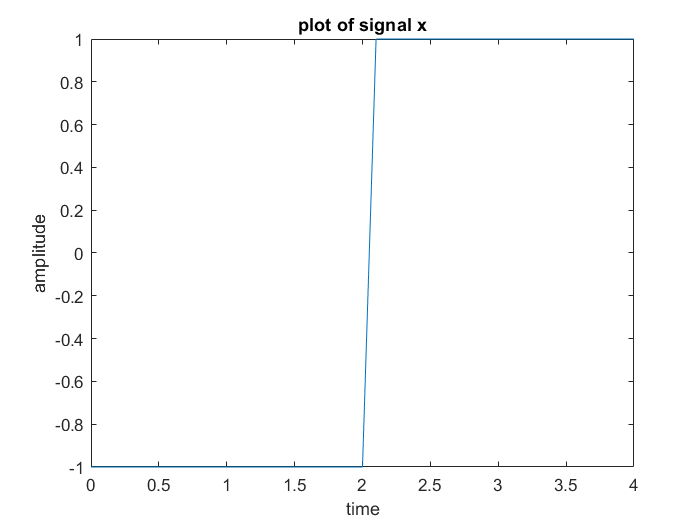

clear all
x1=-1*ones(1,21);
x2=1*ones(1,20);
t=linspace(0,4,(length(x1)+length(x2)));
plot(t, [x1,x2])
title('plot of signal x');
xlabel('time');ylabel('amplitude');

Try to spot a mistake in the previous code!

## Exercise

Write an *.mlx file that explains how to generate a unit step function on MATLAB. Then, include a plot of a unit step function shifted by t=2. 

## Proper Coding Practices

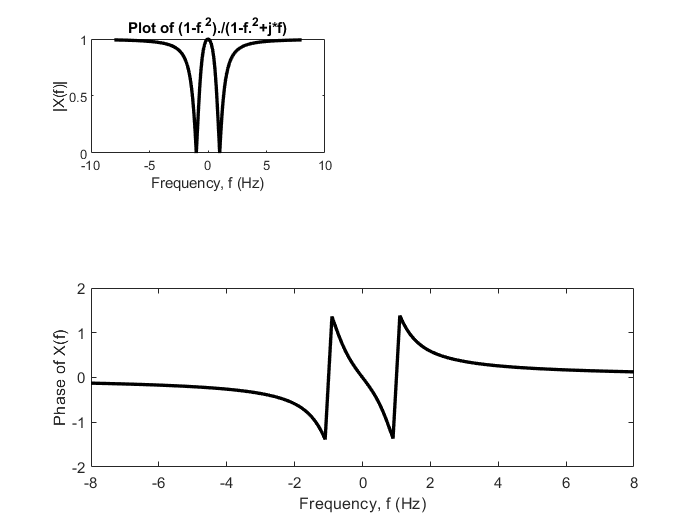

% Program to plot the function, (1-f^2)/(1-f^2+j*f)
%-----------------------------------------------------------------
% This section actually calculates values of the function
%-----------------------------------------------------------------
clear all
df = 1/10 ; % "df" - spacing between frequencies
fmin = -8 ; fmax = 8 ; % "fmin" & "fmax" - beginning and ending
% frequencies
f = fmin:df:fmax ; % "f" - vector of frequencies for
% plotting function with straight lines
% between points
X = (1-f.^2)./(1-f.^2+j*f) ; % "X" - vector of function values
%-----------------------------------------------------------------
% This section displays the results and formats the plots
%-----------------------------------------------------------------

subplot(3,2,1) ; % Plot Three plots, one on top and one on the bottom.

% First draw the top plot.
p = plot(f,abs(X),'k') ; % Plot |X(f)| with black lines between points
set(p,'LineWidth',2) ; % Make the plot line heavier
xlabel('Frequency, f (Hz)') ; % Label the "f" axis
ylabel('|X(f)|') ; % Label the "|X(f)|" axis
title('Plot of (1-f.^2)./(1-f.^2+j*f)') ; % Title the plots

subplot(3,1,2) ; % Draw the second plot.
p = plot(f,angle(X),'k') ; % Plot the phase (angle) of X(f) with black lines between points
set(p,'LineWidth',2) ; % Make the plot line heavier
xlabel('Frequency, f (Hz)') ; % Label the "f" axis
ylabel('Phase of X(f)') ; % Label the "Phase of X(f)" axis

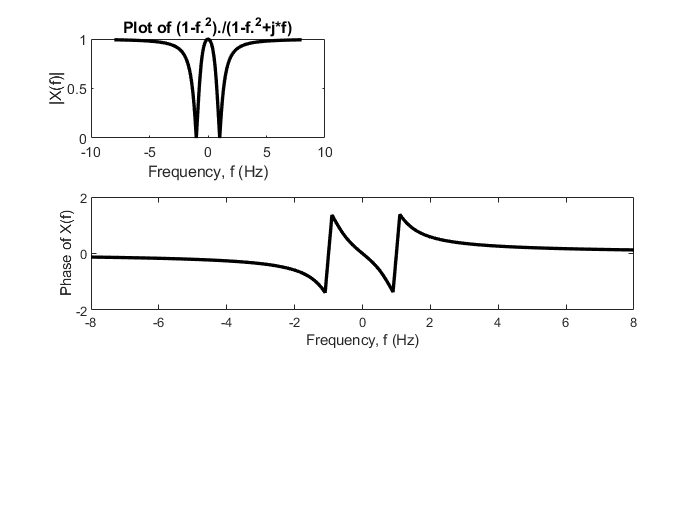


subplot(3,1,2) ; % Draw the second plot.
p = plot(f,angle(X),'k') ; % Plot the phase (angle) of X(f) with black lines between points
set(p,'LineWidth',2) ; % Make the plot line heavier
xlabel('Frequency, f (Hz)') ; % Label the "f" axis
ylabel('Phase of X(f)') ; % Label the "Phase of X(f)" axis